n = dardos

m = alvos

N = 1e4;

a)

n = 20;
m = 100;
p = 1/m;

lancamentos = rand(n,N);
alvo_dardo = ceil(lancamentos*m);

alvos = zeros(m, N);
repetidos = zeros(1,N);

for i = 1:N
    for j = 1:n
        alvos(alvo_dardo(j,i),i) = alvos(alvo_dardo(j,i),i) + 1; %n de dardo em cada alvo
    end
    for j = 1:n
        if  alvos(alvo_dardo(j,i),i) >= 2
            repetidos(i) = repetidos(i) +1; %número de alvos em que tiveram mais de um dardo em cada N
        end
    end
end

P_a = sum(repetidos==0) / N %probabilidade de nenhum alvo ser atingido repetidamente

P_a = 0.1290

b)

P_b = sum(repetidos>=1) / N %probabilidade de pelo menos 1 alvo ser atingido repetidamente

P_b = 0.8710

c)

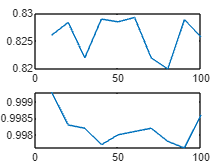

x_alvos = linspace(10,100,10); %n de dardos (10 até 100, passo de 10)

y_1000 = zeros(1,10);
y_100000 = zeros(1,10);

for k = 1:10 %tamanho de x_alvos
    m = 1000; %alvos
    
    lancamentos = rand(n,N);
    alvo_dardo = ceil(lancamentos*m);
    
    alvos = zeros(m, N);
    repetidos = zeros(1,N);
    
    for i = 1:N
        for j = 1:n
            alvos(alvo_dardo(j,i),i) = alvos(alvo_dardo(j,i),i) + 1; %n de dardo em cada alvo
        end
        for j = 1:n
            if  alvos(alvo_dardo(j,i),i) >= 2
                repetidos(i) = repetidos(i) +1; %número de alvos em que tiveram mais de um dardo em cada N
            end
        end
    end

    y_1000(k) = sum(repetidos==0) / N; %probabilidade de nenhum alvo ser atingido repetidamente
    
    m = 100000; %alvos
    
    lancamentos = rand(n,N);
    alvo_dardo = ceil(lancamentos*m);
    
    alvos = zeros(m, N);
    repetidos = zeros(1,N);
    
    for i = 1:N
        for j = 1:n
            alvos(alvo_dardo(j,i),i) = alvos(alvo_dardo(j,i),i) + 1; %n de dardo em cada alvo
        end
        for j = 1:n
            if  alvos(alvo_dardo(j,i),i) >= 2
                repetidos(i) = repetidos(i) +1; %número de alvos em que tiveram mais de um dardo em cada N
            end
        end
    end

    y_100000(k) = sum(repetidos==0) / N; %probabilidade de nenhum alvo ser atingido repetidamente
end

subplot(2,1,1)
plot(x_alvos,y_1000)

subplot(2,1,2)
plot(x_alvos,y_100000)

d)

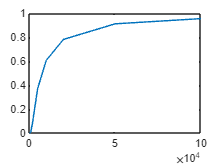

m = [200, 500, 1000, 2000, 5000, 10000, 20000, 50000 , 100000];
n = 100;
y = zeros(1,length(m));

for k = 1:length(m) %tamanho de x_alvos
    lancamentos = rand(n,N);
    alvo_dardo = ceil(lancamentos*m(k));
    
    alvos = zeros(m(k), N);
    repetidos = zeros(1,N);
    
    for i = 1:N
        for j = 1:n
            alvos(alvo_dardo(j,i),i) = alvos(alvo_dardo(j,i),i) + 1; %n de dardo em cada alvo
        end
        for j = 1:n
            if  alvos(alvo_dardo(j,i),i) >= 2
                repetidos(i) = repetidos(i) +1; %número de alvos em que tiveram mais de um dardo em cada N
            end
        end
    end
    y(k) = sum(repetidos==0) / N; %probabilidade de nenhum alvo ser atingido repetidamente
end

figure;
plot(m,y)